# **Computer Assignment 1: Spectral Analysis of EEG**

**Task 1: Calculate the power spectrum estimates of the EEG signal using the Welch's method **

Use two different sets of parameters:

1) One yielding a spectral estimate of relatively high variance, i.e. the signal looks noisy

2) One yielding a considerably more smooth spectral estimate. 

Useful commands

Welch's method:` pwelch(`[`x`](https://www.mathworks.com/help/releases/R2021b/signal/ref/pwelch.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OT%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WL&docviewer=helpbrowser&docrelease=R2021b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31517%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DDASLV7&searchsource=mw&snc=AXX4FO&container=jshelpbrowser#btuf68p_sep_shared-x)`,`[`window`](https://www.mathworks.com/help/releases/R2021b/signal/ref/pwelch.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OT%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WL&docviewer=helpbrowser&docrelease=R2021b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31517%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DDASLV7&searchsource=mw&snc=AXX4FO&container=jshelpbrowser#shared-window)`,`[`noverlap`](https://www.mathworks.com/help/releases/R2021b/signal/ref/pwelch.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OT%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WL&docviewer=helpbrowser&docrelease=R2021b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31517%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DDASLV7&searchsource=mw&snc=AXX4FO&container=jshelpbrowser#btuf68p-noverlap)`,`[`nfft`](https://www.mathworks.com/help/releases/R2021b/signal/ref/pwelch.html?doclanguage=en&nocookie=true&prodfilter=ML%20SL%205G%20AE%20AT%20AA%20AU%20DR%20AS%20BI%20CM%20VP%20CT%20CF%20DA%20DB%20DF%20DD%20DH%20NN%20DS%20ET%20EC%20FH%20IT%20FI%20PO%20FL%20GD%20GC%20HD%20ES%20IA%20IP%20IC%20LP%20LS%20MG%20ME%20CO%20MJ%20MR%20AM%20MP%20MB%20MT%20NV%20OT%20OP%20DM%20PD%20AR%20PW%20PM%20RA%20RL%20RB%20RP%20RF%20RK%20RO%20RC%20RR%20SI%20TF%20SX%20SQ%20SG%20SB%20SE%20SS%20LD%20PS%20SH%20MS%20VR%20VV%20CI%20RT%20SK%20SD%20CV%20SO%20DV%20WT%20PL%20XP%20SR%20RQ%20SZ%20HW%20EL%20SF%20ST%20SM%20ZC%20ID%20TA%20UV%20VE%20VN%20VT%20WA%20LH%20WL&docviewer=helpbrowser&docrelease=R2021b&s_cid=pl_webdoc&loginurl=https%3A%2F%2Flocalhost%3A31517%2Ftoolbox%2Fmatlab%2Fmatlab_login_framework%2Fweb%2Findex.html%3Fsnc%3DDASLV7&searchsource=mw&snc=AXX4FO&container=jshelpbrowser#btuf68p-nfft)`,fs)`

`     x = input signal; window = Hamming window length; noverlap = number of overlapping samples; nfft = number of discrete DFT points`

`    e.g. pwelch[x, 128, 64, 128, fs].`

Plotting, e.g.:` figure, plot, title, xlabel, ylabel`

**Note: **If your data is not oscillating around zero, you can shift it by substracting the mean values from the data, e.g.` EEG - mean(EEG)`

isi = 0.0050

fs = 200

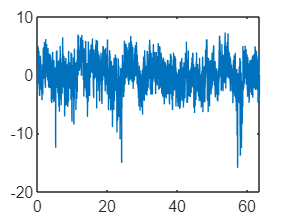

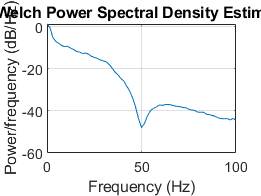

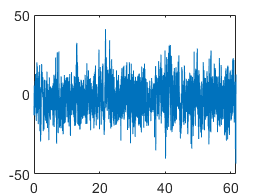

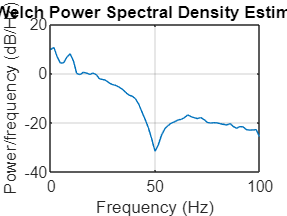

% ADD YOUR CODE HERE7
fs = ;

**Task 2: Perform time-frequency analysis on the EEG signal**

Use again two sets of parameters, similarly to Task 1. 

Useful commands

`spectrogram(x, window, noverlap, f, fs) `

`    e.g. spectrogram(x, 128, 64, 128, fs)`

Color scale manipulation `set(gca, 'Clim', [-100 45]);`

Plotting, e.g.:` figure, plot, title, xlabel, ylabel`

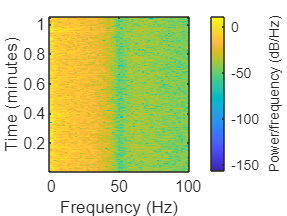

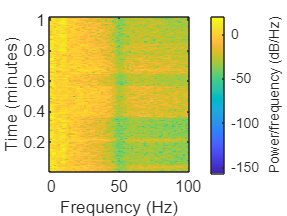

% ADD YOUR CODE HERE
